Se cargan variables para recuperar la señal y sus parametros relevantes. También se definen variables para crear objetos tipo Rayleigh

load generador
sampleRate500kHz = 500e3; % Sample rate of 500K Hz
sampleRate20kHz  = 20e3; % Sample rate of 20K Hz
maxDopplerShift  = 5; % Maximum Doppler shift of diffuse components (Hz)
delayVector = (0:5:15)*1e-6; % Discrete delays of four-path channel (s)
gainVector  = [0 -3 -6 -9]; % Average path gains (dB)
numSamples = 1; %Muestras afectadas por Rayleigh

Declaración de los parametros del filtro conformador de pulsos y sus valores

%***********PRUEBAS FILTRO**************
rolloff = 0.25; % Filter rolloff
span = 6;       % Filter span
sps = 4;        %Muestras por simbolo

Respuesta en frecuencia e la señal antes del canal........

Creación del filtro y proceso de filtrado de la señal "y" modulada. Se hace un proceso de adición de redundancia a la señal y se pasa por un filtro raiz de coseno alzado:

FiltroConf = rcosdesign(rolloff, span, sps);
ytx = upfirdn(ymod, FiltroConf, sps)

ytx =   -0.0188 + 0.0188i
   0.0030 - 0.0030i
   0.0327 - 0.0327i
   0.0471 - 0.0471i
   0.0453 - 0.0078i
  -0.0305 + 0.0245i
  -0.1179 + 0.0525i
  -0.1465 + 0.0524i
  -0.0775 - 0.0132i
   0.1496 - 0.0885i


Inyección de ruido blando gaussiano a la señal resultante del filtro

EbNop = 10;
snrp = EbNop + 10*log10(k) - 10*log10(sps);
yrx = awgn(ytx, snrp, 'measured')

yrx =   -0.0699 + 0.1219i
  -0.4325 - 0.0751i
  -0.0692 + 0.0736i
   0.1585 - 0.0436i
   0.2320 + 0.0696i
  -0.2464 + 0.1755i
  -0.4103 + 0.1701i
   0.1572 + 0.1292i
  -0.0587 - 0.4884i
   0.0100 + 0.1977i


Se observa la señal recibida con el ruido añadido en el tiempo, se usa el mismo algoritmo explicado en el generador:

RR=real(yrx);  %parte real de yrx
II=imag(yrx);  %parte imaginaria de yrx
m2=[];
for (i=1:1:round(length(RR)/1000))        %Generar señal modulada en el dominio del tiempo
    yr=RR(i)*cos(2*pi*f*t);                     %Componente real en fase
    yim=II(i)*sin(2*pi*f*t);            % Componenete imaginario cuadratura 
    y=yr+yim;
    m2=[m2 y];
end
tt=sp/100:sp/100:sp*round(length(RR)/1000);  %eje horizontal
figure
plot(tt,m2)
xlim([0 4])  % limitar el eje x
pbaspect([1 0.5 1])  %dimensionar aspecto
title('Forma de onda para la señal en el canal');
xlabel('tiempo(segundos)');
ylabel('Amplitud(voltaje)');

Configuración de modulo Rayleigh a partir de las variables definidas al inicio y se simula un tramo del canal que perturbará la señal con el efecto de desvanecimiento Rayleigh:

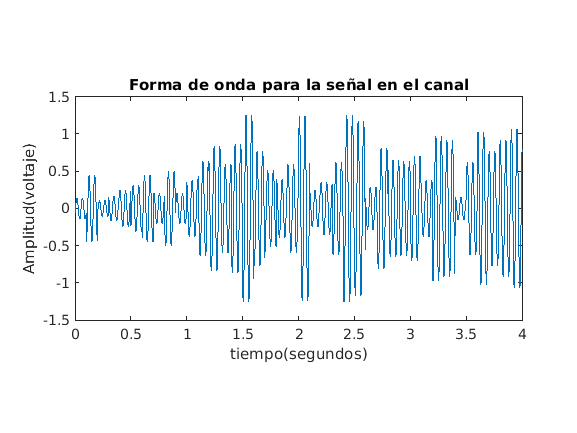

rayChan = comm.RayleighChannel( ...
    'PathDelays',delayVector, ...
    'AveragePathGains',gainVector, ...
    'RandomStream','mt19937ar with seed', ...
    'SampleRate',sampleRate500kHz, ...
    'MaximumDopplerShift',maxDopplerShift, ...
    'Seed',10, ...
    'PathGainsOutputPort',true);

%La señal saliente de awgn pasa por el efecto Rayleigh
yrxRay=rayChan(yrx(1:numSamples)); 

release(rayChan);

rayChan.Visualization = 'Impulse and frequency responses';
rayChan.SamplesToDisplay = '100%';

%Mostrar respuestas en impulso y frecuencia
%para dos iteraciones en los primeros 500 simbolos
%de la señal. Graficas dinamicas
numFrames = 2;
for i = 1:numFrames
    rayChan(yrx(1:numSamples));
end

hold off

Se elimina la redundancia y se acomoda la señal para coincidir en longitud con la que entró al filtro sin alterar la información agregada por los otros módulos:

yrxRay= [yrxRay ; yrx(numSamples+1:end)]; %unir la señal otra vez
yrxfiltp = upfirdn(yrxRay, FiltroConf, 1, sps);
yrxfiltp = yrxfiltp(span+1:end-span)

yrxfiltp =    0.7794 - 0.9246i
  -1.1988 - 0.7853i
   1.0635 + 1.0280i
  -0.8668 - 1.4777i
   0.8055 - 1.0286i
  -0.8557 - 0.7353i
   0.8734 + 1.2240i
   1.1123 + 0.8959i
  -0.9942 - 0.7825i
   1.1410 - 0.7111i


Señal filtrada en el dominio del tiempo:

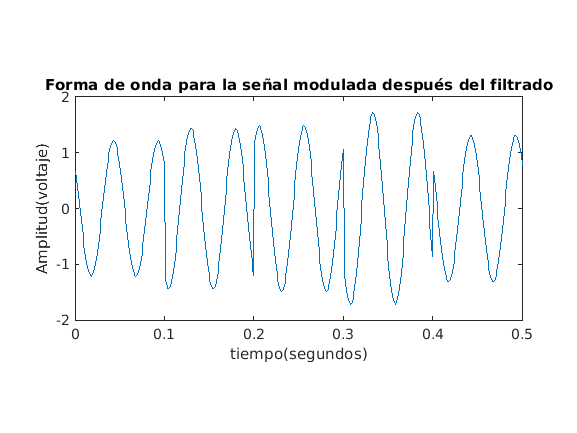


RR=real(yrxfiltp);  %parte real de yrx
II=imag(yrxfiltp);  %parte imaginaria de yrx
m1=[];
for (i=1:1:round(length(RR)))        %Generar señal modulada en el dominio del tiempo
    yr=RR(i)*cos(2*pi*f*t);                     %Componente real en fase
    yim=II(i)*sin(2*pi*f*t);            % Componenete imaginario cuadratura 
    y=yr+yim;
    m1=[m1 y];
end
tt=sp/100:sp/100:sp*round(length(RR));  %eje horizontal
plot(tt,m1)
xlim([0 0.5])  % limitar el eje x   //// TOMAR CON 20 s
pbaspect([1 0.5 1])  %dimensionar aspecto
title('Forma de onda para la señal modulada después del filtrado');
xlabel('tiempo(segundos)');
ylabel('Amplitud(voltaje)');
hold off

Diagrama de constelación para simbolos afectados por Rayleigh

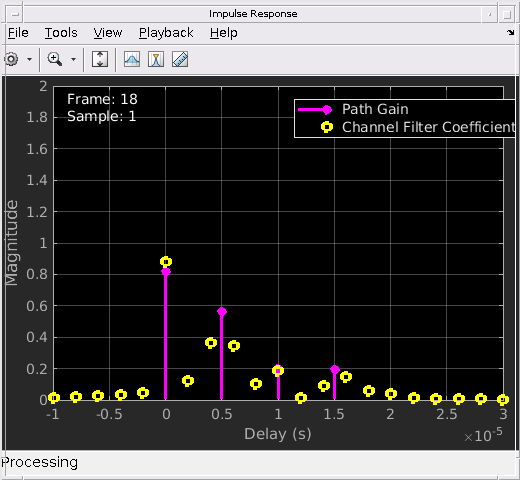

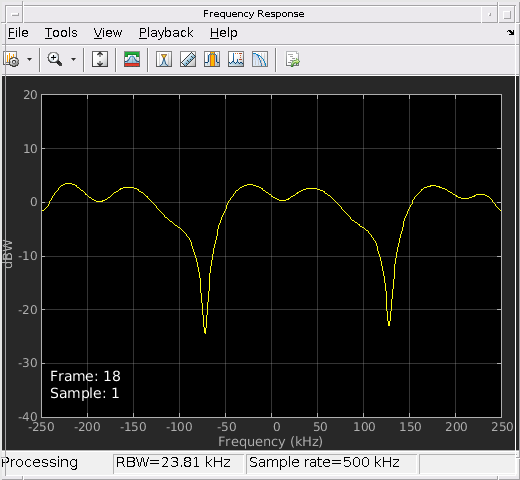

constDiag = comm.ConstellationDiagram( ...
    'Name','Received Signal After Rayleigh Fading');
%Mostrar etapas del diagramas en 16 iteraciones
numFrames = 16;
for n = 1:numFrames
    constRay = rayChan(ymod(1:numSamples));
    % Mostrat diagrama de constelación para 
    %simbolos afectados por Rayleigh
    constDiag(constRay);
end

Efecto Rayleigh en el tiempo

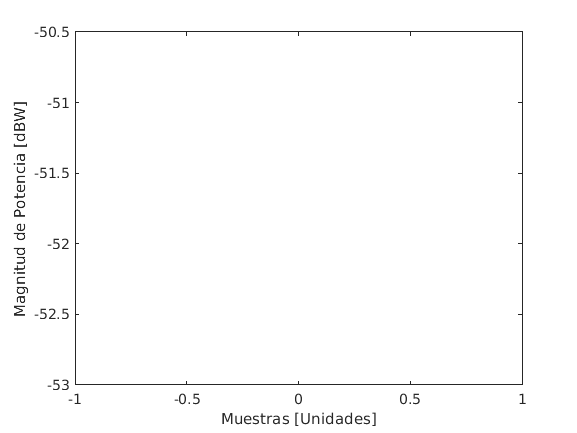

ns = (0:numSamples-1)';
plot(ns,20*log10(abs(yrxRay(1:numSamples))))
xlabel('Muestras [Unidades]')
ylabel('Magnitud de Potencia [dBW]')

%−20 dBW (0.01 W)

Gráfica de comparación entre la señal recibida antes y después del filtrado, en donde se recupera la señal enviada:

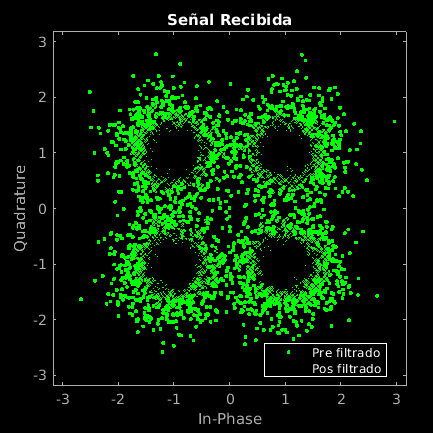

%se grafican 5000 simbolos para evitar saturar el plot
hScatter = scatterplot(sqrt(sps)* ...
    yrxRay(1:sps*5000),...
    sps,0,'g.');
hold on
%superponer simbolos pos filtrados en simbolos
%pre filtrados visualmente
scatterplot(yrxfiltp(1:5000),1,0,'kx',hScatter)
title('Señal Recibida')
legend('Pre filtrado','Pos filtrado') % rango de los ejes
hold off

Ecualización de tipo Decision FeedBack utilizando el algoritmo LMS con el cual se compensa levemente el ISI y mejora la señal.

numTrainingSymbols = 5000;
eq=comm.LinearEqualizer('Algorithm','LMS','NumTaps',3,'ReferenceTap',1,...
    'StepSize',0.01,'AdaptWeightsSource','Input port','Constellation',qammod([0:M-1],M))

eq =   comm.LinearEqualizer with properties:

                Algorithm: 'LMS'
                  NumTaps: 3
                 StepSize: 0.0100
            Constellation: [-1.0000 + 1.0000i -1.0000 - 1.0000i 1.0000 + 1.0000i 1.0000 - 1.0000i]
             ReferenceTap: 1
               InputDelay: 0
    InputSamplesPerSymbol: 1
    TrainingFlagInputPort: false
       AdaptAfterTraining: true
     InitialWeightsSource: 'Auto'
       WeightUpdatePeriod: 1


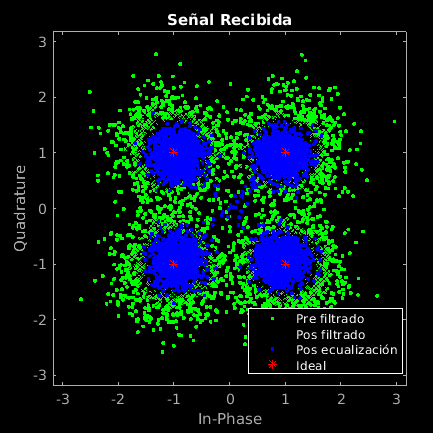



[yrxeq,err,weights] = eq(yrxfiltp(1:numTrainingSymbols),ymod(1:numTrainingSymbols));
yrxfinal=[yrxeq ; yrxfiltp(numTrainingSymbols+1:end)];

hScatter = scatterplot(sqrt(sps)* ...
    yrxRay(1:sps*5000),...
    sps,0,'g.');
hold on
%superponer simbolos pos filtrados en simbolos
%pre filtrados visualmente
scatterplot(yrxfiltp,1,0,'kx',hScatter)
hold on
scatterplot(yrxeq,1,0,'b.',hScatter)
hold on
scatterplot(ymod,n,0,'r*',hScatter)
title('Señal Recibida')
legend('Pre filtrado','Pos filtrado','Pos ecualización','Ideal') % rango de los ejes
%axis([-4 4 -4 4])
hold off

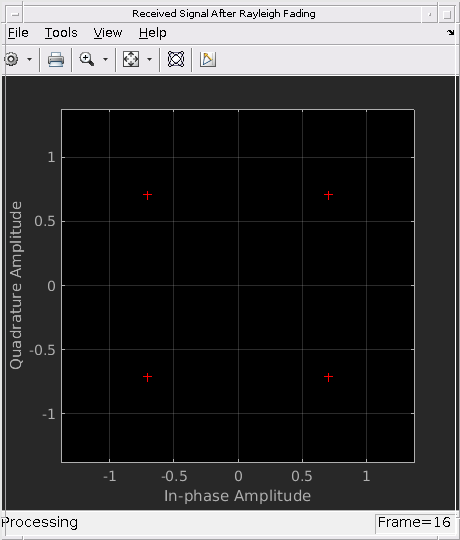


save canal